run('init')

csv_file = fopen('F.csv','rt');
fgets(csv_file);
C1 = textscan(csv_file, '%s%s', 'Delimiter', ';');
V = str2double(C1{1});
Fa_input = str2double(regexprep(C1{2}, ',', '.'));
fclose(csv_file);

csv_file = fopen('Wind.csv','rt');
fgets(csv_file);
C2 = textscan(csv_file, '%s%s%s', 'Delimiter', ';');
Y = str2double(C2{1});
Wx = str2double(regexprep(C2{2}, ',', '.'));
Wz = str2double(regexprep(C2{3}, ',', '.'));
fclose(csv_file);

p = polyfit(V, Fa_input, 2);

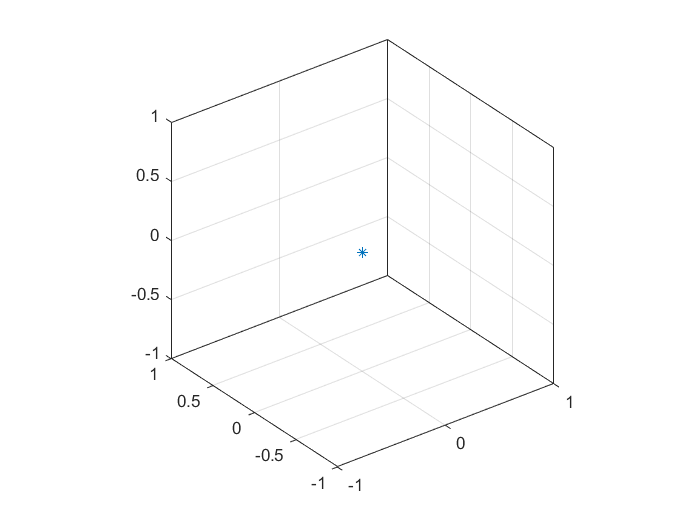

g=9.81;
G=m*g;
plot3(0,0,0,"*")
axis square
grid on
box on
hold on
if all == true
    x = [];
    z = [];
    y = [];
    for i=0:360
        alfa=pi/180*i;
        x0=0;
        z0=0;
        sim('a');
        x0=-out.Data(end,2);
        z0=-out.Data(end,3);
        sim('a');
        plot3(out.Data(:,2)',out.Data(:,3)',out.Data(:,1)')
        if mod(i,50)==0
            disp(i)
        end
    end
    hold off
else
    hold off
    alfa=0;
    x0=0;
    z0=0;
    sim('a')
    x0=-out.Data(end,2);
    z0=-out.Data(end,3);
    sim('a');
    
    csv_file = fopen('out.csv','w');
    len = size(out.Data(:,1));
    fprintf(csv_file,'t;y;x;z\n');
    for i=1:len
       fprintf(csv_file,'%f;%f;%f;%f\n',out.Time(i),out.Data(i,1),out.Data(i,2),out.Data(i,3)); 
    end
    fclose(csv_file);
end